# 繪圖軟體應用 第16周(12/25)

## Rotating Christmas tree

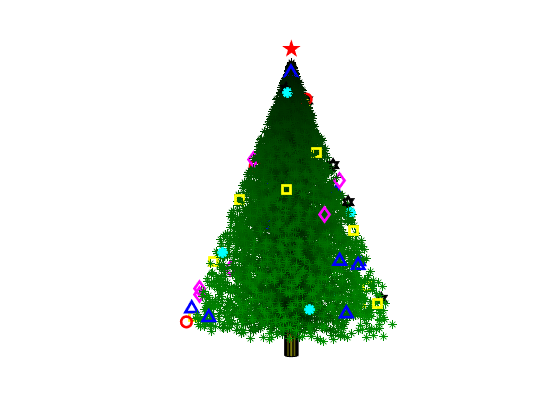

% -------------------------------------------------------------------------
clear, clc, close all
figure, hold on, N = 6^5; c = 50; k = randi(6,c,1); l = randperm(N,c);
q = @(x) rand(N,1); a = q()*2*pi; z = q(); r = .4*(1-z); t = q();
x = r.*cos(a); y = r.*sin(a); P = {'ro','ys','md','b^','kh','c*'};
scatter3(x.*t,y.*t,z,[],[zeros(N,1) (t.*r).^.6 zeros(N,1)],'*')
plot3(0,0,1.05,'rp','markers',12,'markerf','r')
for i = 1:6
    L = l(k==i);
    plot3(x(L),y(L),z(L),P{i},'markers',8,'linew',2);
end
[X,Y,Z] = cylinder(.025,30);
surf(X,Y,-Z*.1)
view(3, 9), axis equal off
for i = 1:9:c*9, set(gca,'vie',[i, 9]); drawnow, end

%--------------------------------------------------------------------------